% Train and test all data with one classifier

clear;
clc;

% ii=1;
% ii=7
F=[];
W=[];
for ii = 1:7
    number =int2str(ii);
    fname = ['Perturb_Data New/Chamber',number,'F.csv'];
    wname = ['Perturb_Data New/Chamber',number,'W.csv'];
    labels = categorical(["Fail","Working"]);
    F=[F; readmatrix(fname)];
    W=[W; readmatrix(wname)];
end

%Slice Data into chunks
chunkSize = 192; % Define the size of each chunk

numChunksF = ceil(size(F, 1) / chunkSize); % Calculate the number of chunks
numChunksW = ceil(size(W, 1) / chunkSize); % Calculate the number of chunks

chunksF = cell(numChunksF-1, 7); % Preallocate a cell array to hold the chunks
chunksW = cell(numChunksW-1, 7); % Preallocate a cell array to hold the chunks
offset = 90; % offset at the start

%fail case
for i = 1:numChunksF-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx =   min(offset+(i * chunkSize), size(F, 1));
    for j = 1:6
        chunksF{i,j} = F(startIdx:endIdx, j);
    end
    chunksF{i,7}=labels(1);
end

%working case
for i = 1:numChunksW-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx = min(offset+(i * chunkSize), size(W, 1));
    for j = 1:6
        chunksW{i,j} = W(startIdx:endIdx, j);
    end
    chunksW{i,7}=labels(2);
end

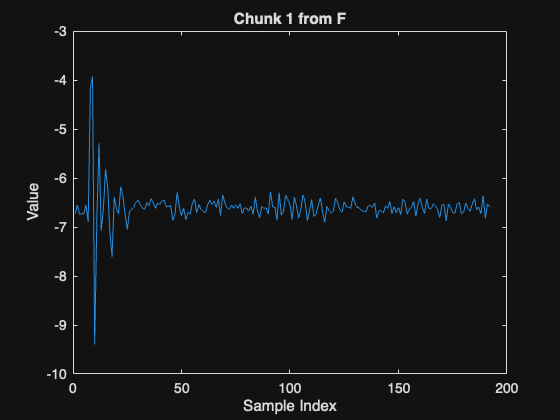

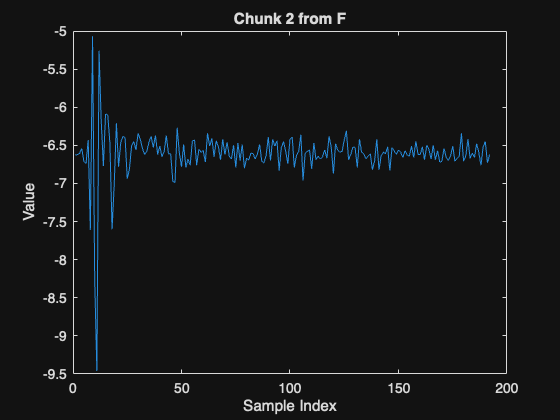

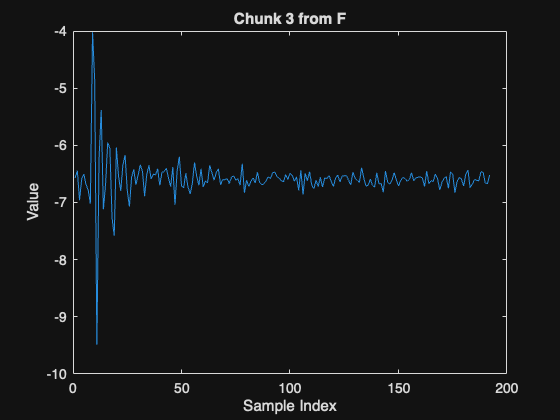

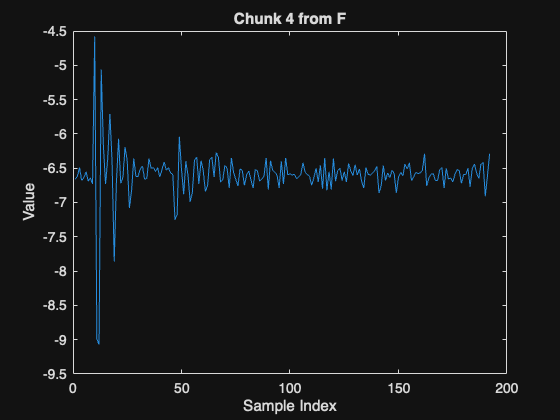

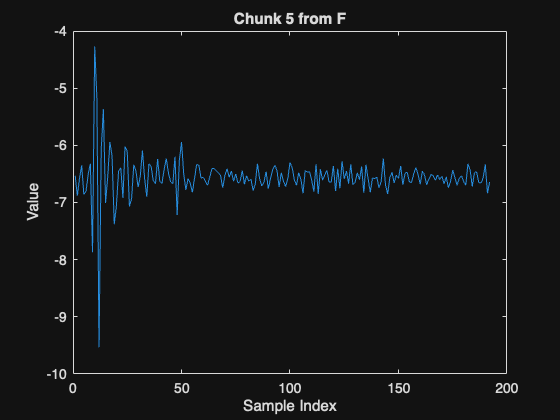

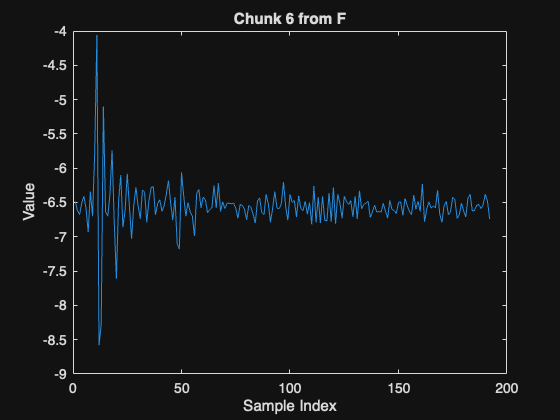

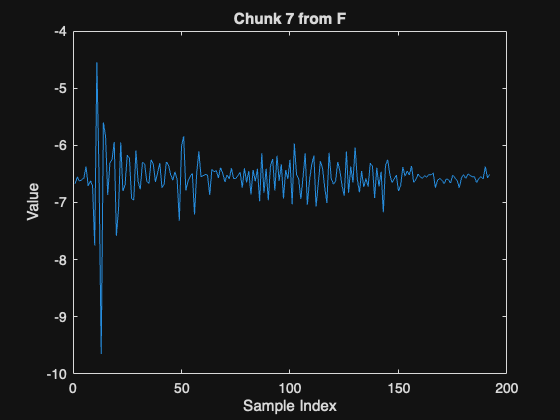

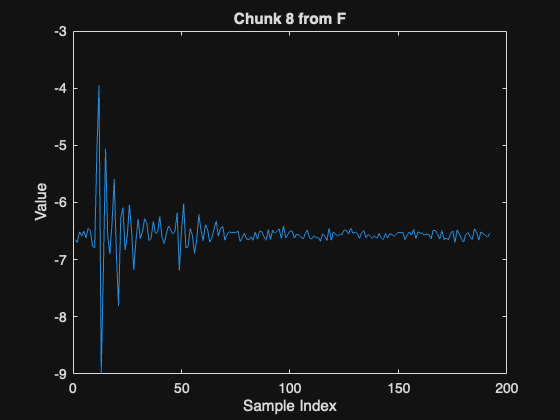

% Visualize 10 chunks from each cell fail
for i = 1:min(10, numChunksF)
    figure;
    plot(chunksF{i});
    title(['Chunk ', int2str(i), ' from F']);
    xlabel('Sample Index');
    ylabel('Value');
end

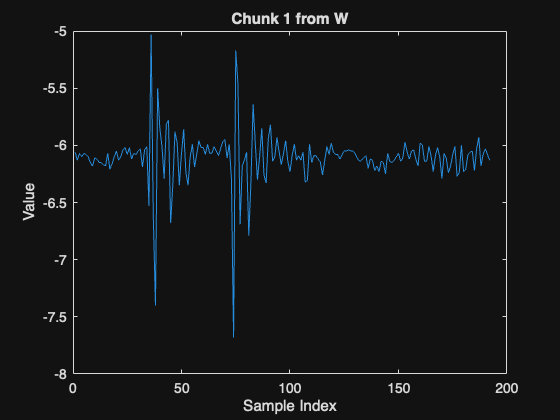

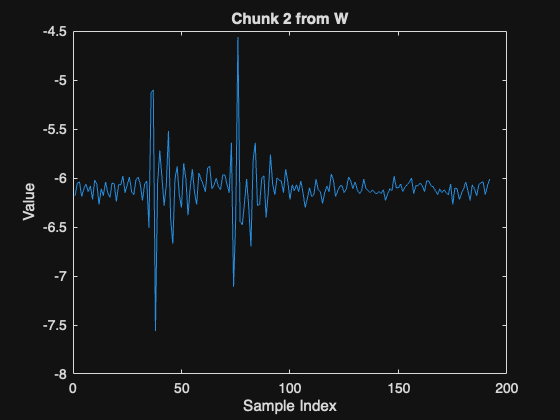

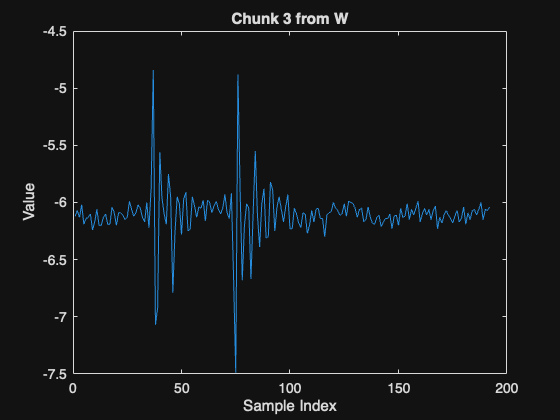

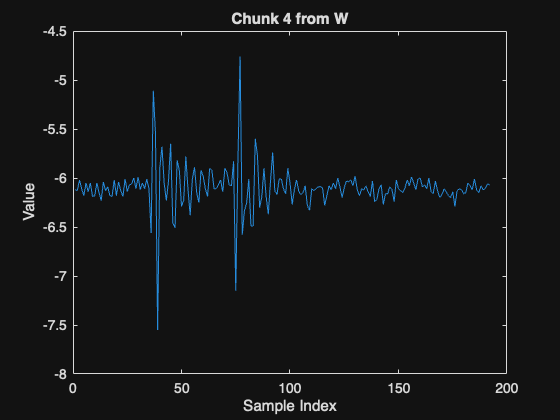

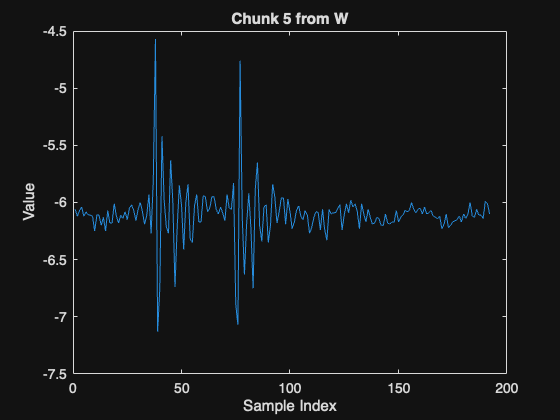

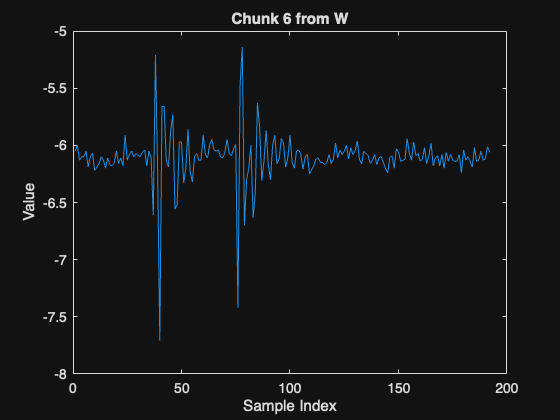

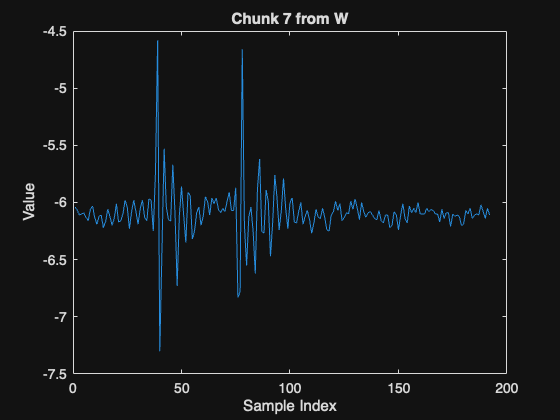

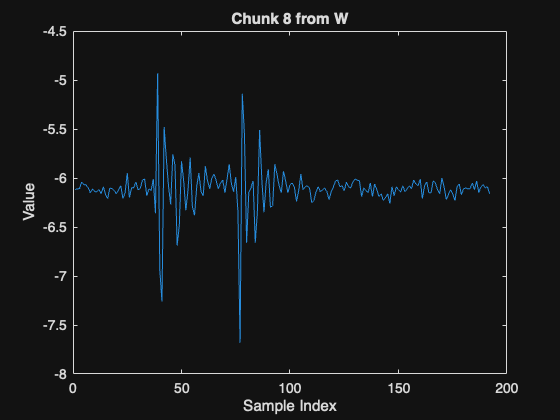


% Visualize 10 chunks from each cell working
for i = 1:min(10, numChunksW)
    figure;
    plot(chunksW{i+60});
    title(['Chunk ', int2str(i), ' from W']);
    xlabel('Sample Index');
    ylabel('Value');
end

% Create a table containing 7 columns (6 signals + 1 label)

data = [chunksW;chunksF];
data = cell2table(data);
data.Properties.VariableNames = {'Ax','Ay','Az','Gx','Gy','Gz','label'};

% for ii =1:7
%     sname = sprintf('Perturb_Data_Sim/SimFail_Full_Ch %d.mat',ii);
%     dataf = load(sname);
%     chunksF =dataf. dataTable;
%     data = [data;chunksF];
% end



%Extract top 10 features (Ranked by t-test)

features = GenerateTop10Features(data);

%Create test-train split
rng(0)
idx = cvpartition(features.label, "HoldOut",0.3);
featureTrain = features(idx.training,:);
featureTest = features (idx.test,:);

featuresAfter = helperExtractLabeledData(featureTrain, ...
   "Working");

featureDimension = 10;

% Define Fully Connected network layers
layers = [
    sequenceInputLayer(featureDimension, Name="input", Normalization="zscore")

    % ----- Encoder -----
    convolution1dLayer(3, 16, Padding="same", Name="conv1")
    reluLayer(Name="relu1")
    convolution1dLayer(3, 8, Padding="same", Name="conv2")
    reluLayer(Name="relu2")
    maxPooling1dLayer(2, Name="pool1")  % Reduces time dimension

    % ----- Bottleneck -----
    convolution1dLayer(3, 4, Padding="same", Name="bottleneck_conv")
    reluLayer(Name="relu_bottleneck")

    % ----- Decoder -----
    transposedConv1dLayer(3, 8, Cropping="same", Name="deconv1")
    reluLayer(Name="relu3")
    transposedConv1dLayer(3, 16, Cropping="same", Name="deconv2")
    reluLayer(Name="relu4")
    transposedConv1dLayer(3, featureDimension, Cropping="same", Name="reconstruction")
];
% Set Training Options
% options = trainingOptions('adam', ...
%    'Plots', 'training-progress', ...
%    'Metrics', 'rmse', ...
%    'MiniBatchSize', 600,...
%    'MaxEpochs',120, ...   
%    'Verbose',false);

options = trainingOptions('adam', ...
   'Metrics', 'rmse', ...
   'MiniBatchSize', 20,...
   'MaxEpochs',120, ...   
   'Verbose',false);

net = trainnet(featuresAfter, featuresAfter, layers, "mse", options);

Error using trainnet (line 58)
Invalid network.

Caused by:
    Layer 'pool1': The size of the pooling dimension of the padded input data must be larger than or equal to the pool size. For networks with sequence input, this check depends on the MinLength property of the sequence input layer. To ensure that this check is accurate, set MinLength to the shortest sequence length of your training data.

testNormal = featureTest(20, 2:end).Variables;
testAnomaly = featureTest(40, 2:end).Variables;

% Predict decoded signal for both
reconstructedNormal = predict(net,testNormal);
reconstructedAnomaly = predict(net,testAnomaly);

% Visualize
helperVisualizeModelBehavior(testNormal, testAnomaly, reconstructedNormal, reconstructedAnomaly)

% Extract data before maintenance
XTestBefore = helperExtractLabeledData(featureTest, "Fail");

% Predict output before maintenance and calculate error
yHatBefore = minibatchpredict(net, XTestBefore, 'UniformOutput', true);
errorBefore = helperCalculateError(XTestBefore, yHatBefore);

% Extract data after maintenance
XTestAfter = helperExtractLabeledData(featureTest, "Working");

% Predict output after maintenance and calculate error
yHatAfter = minibatchpredict(net, XTestAfter, 'UniformOutput', true);
errorAfter = helperCalculateError(XTestAfter, yHatAfter);

helperVisualizeError(errorBefore, errorAfter);

XTestAll = helperExtractLabeledData(featureTest, "All");

yHatAll = minibatchpredict(net, XTestAll, 'UniformOutput', true);
errorAll = helperCalculateError(XTestAll, yHatAll);

thresh = 0.66;
anomalies = errorAll > thresh*mean(errorAll);

helperVisualizeAnomalies(anomalies, errorAll, featureTest);

